# Methionine uptake rate titration

**Author**: Scott Campit

## Summary

## Initialize COBRA

Below are several preprocessig steps, including:

- Setting biomass objective function

- Lowering methionine substrate uptake rate 

- Setting up params for iMAT (default settings used with pFBA)

- Assigning the activity through demand reactions to be 0.0625. based on a previous analysis with nutrient supplementation and deprivation.

% Initialize metabolic modeling components
clear all;
initCobraToolbox; changeCobraSolver('gurobi', 'all');



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2020
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.26.2).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

load ~/Data/CBM/MetabolicModels/eGEM/07132020.mat;    % Latest version of eGEM
load ~/Data/CBM/eGEM/Old/shenEtAl2019.mat ...
         labels media_exchange1 mediareactions1;      % Substrate uptake rates and exchange reaction names
% Update BiGG exchange reaction notation 
mediareactions1 = strrep(mediareactions1, '(', '_');
mediareactions1 = strrep(mediareactions1, ')', '');

Set the objective function to maximize biomass

% Set up objective function
eGEM.c = zeros(size(eGEM.c));
eGEM.c(string(eGEM.rxns) == 'biomass_objective') = 1;

Get a list of demand reactions

% Get list of demand reactions from eGEMM
pos = [3770, 3775:3777];
dm_reactions = string(eGEM.rxns(pos))'

dm_reactions = 1×4 string array
    "DM_bulk_methylation"    "DM_KMe1"    "DM_KMe2"    "DM_KMe3"


Set the lower bound for methionine uptake

% Set methionine lower bound to a really small number
[~, metUptakePos] = ismember({'EX_met_L_e'}, eGEM.rxns);
met_uptake = [-1E-12, -2.5E-12, -5E-12, -7.5E-12, ...
              -1E-6, -2.5E-6, -5E-6, -7.5E-6, ...
              -1E-2, -2.5E-2, -5E-2, -7.5E-2, ...
              -0.1 , -0.25,   -0.5,  -0.75, ...
              -1,    -2.5,    -5,    -7.5, ...
              -10,   -25,     -50,   -75, ...
              -100,  -250,    -500,  -750];

Assign values of parameters for the iMAT algorithm.

% Params for constrain flux regulation. Set all to empty.
onreactions = {};     offreactions = {};
hyperparams.eps = []; hyperparams.isgenes = true;
hyperparams.kap = []; hyperparams.eps2 = [];
hyperparams.rho = []; hyperparams.pfba = false;
hyperparams.kap2 = [];

Set the activity coefficient for demand reactions to be a fixed value, based on the medium perturbation experiments I ran with this current iteration of the eGEMM.

#### Fixed epsilon values

% Activity coefficient for demand reactions
epsilon_methylation = 0.069;

## Nutrient perturbation with various methionine uptake rates.

The final size of each matrix for any given epsilon value should be `50x27` for 50 nutrients by 27 demand reactions. Each matrix is stored as a cell corresponding to a given `epsilon` value.

% Save the data
filename = '~/Data/CBM/eGEM/NutrientPerturbation/08062020_metUptake.mat';
save(filename);

### Methionine Supplementation

for i = 1:length(met_uptake)
    tmp = eGEM;

    % Demand reaction layer
    for j = 1:length(dm_reactions)
        [~, rxnPos] = ismember(dm_reactions(j), tmp.rxns);
        kappa  = 10; 
        
        tmp2 = tmp;
        tmp2.lb(metUptakePos) = met_uptake(i) * kappa;

        % Linear optimization to get flux and growth rate
        [~, solution] = CFR(tmp2, hyperparams, onreactions, offreactions);
        
        % Optimize histone reaction only
        tmp3           = tmp2;
        tmp3.c(rxnPos) = 0.065;
        tmp3.c(3743)   = 0;
        tmp3.lb(3743)  = solution.x(3743) * 0.99;
        
        [~, solution] = CFR(tmp3, hyperparams, onreactions, offreactions);
        
        % Save flux and growth rate based on supplementation / deprivation
        supplementation_flux(i, j)  = solution.x(rxnPos);
        supplementation_grate(i, j) = solution.x(3743);
    end
end
save(filename, ...
     'supplementation_flux', 'supplementation_grate', ...
     '-append');
clear tmp tmp2 tmp3

### Methionine Deprivation

for i = 1:length(met_uptake)
    tmp = eGEM;
    tmp.lb(metUptakePos) = met_uptake(i);

    % Demand reaction layer
    for j = 1:length(dm_reactions)
        [~, rxnPos] = ismember(dm_reactions(j), tmp.rxns);
        kappa  = 0.01; 
                
        % Add activity to demand reactions
        tmp2 = tmp;
        tmp2.lb(metUptakePos) = met_uptake(i) * kappa;

        % Linear optimization to get flux and growth rate
        [~, solution] = CFR(tmp2, hyperparams, onreactions, offreactions);
        
        % Optimize histone reaction only
        tmp3           = tmp2;
        tmp3.c(rxnPos) = 0.065;
        tmp3.c(3743)   = 0;
        tmp3.lb(3743)  = solution.x(3743) * 0.99;
        
        [~, solution] = CFR(tmp3, hyperparams, onreactions, offreactions);
        
        % Save flux and growth rate based on supplementation / deprivation
        deprivation_flux(i, j)  = solution.x(rxnPos);
        deprivation_grate(i, j) = solution.x(3743);
    end
end
save(filename, ...
     'deprivation_flux', 'deprivation_grate', ...
     '-append');
clear tmp tmp2 tmp3

## Evaluate the methionine substrate uptake rate

load ~/Data/CBM/eGEM/NutrientPerturbation/08062020_metUptake.mat
% Colormap
redbluecmap = imresize(redbluecmap, [1000, 3]); 
redbluecmap = min(max(redbluecmap, 0), 1);

Next, we'll set up the labels for the axes

% X-axis labels
dm_labels = strrep(dm_reactions, '_', ' ');
dm_labels = strrep(dm_labels, 'DM', '');

% Y-axis labels (as string)
met_uptake = ["-1E-12", "-2.5E-12", "-5E-12", "-7.5E-12", ...
              "-1E-6", "-2.5E-6", "-5E-6", "-7.5E-6", ...
              "-1E-2", "-2.5E-2", "-5E-2", "-7.5E-2", ...
              "-0.1" , "-0.25",   "-0.5",  "-0.75", ...
              "-1",    "-2.5",    "-5",    "-7.5", ...
              "-10",   "-25",     "-50",   "-75", ...
              "-100",  "-250",    "-500",  "-750"];

Shown are heatmaps of the methionine supplementation and deprivation fluxes and growth rates.

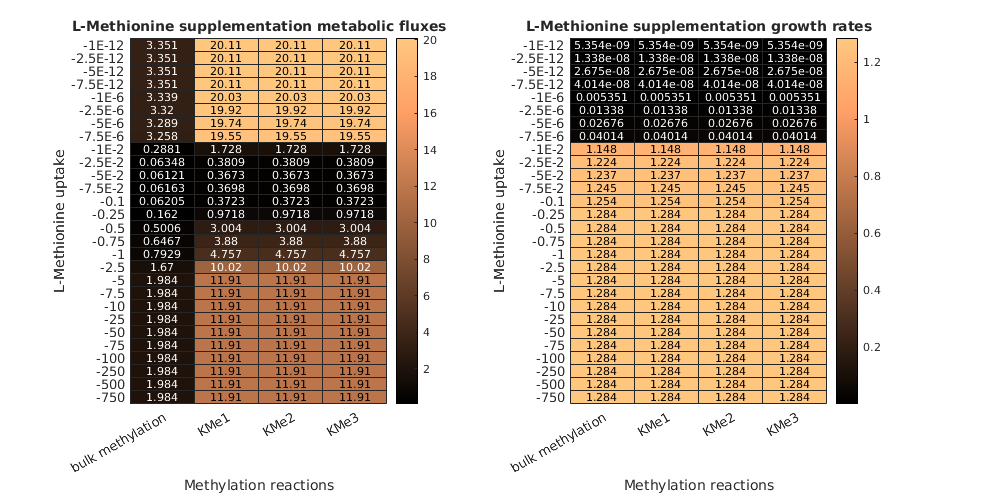

figure
subplot(1, 2, 1)
heatmap(supplementation_flux, ...
    'XData', dm_labels, ...
    'YData', met_uptake', ...
    'Colormap', copper);
xlabel("Methylation reactions"); ylabel("L-Methionine uptake");
title("L-Methionine supplementation metabolic fluxes");
subplot(1, 2, 2)
heatmap(supplementation_grate, ...
    'XData', dm_labels, ...
    'YData', met_uptake', ...
    'Colormap', copper);
xlabel("Methylation reactions"); ylabel("L-Methionine uptake");
title("L-Methionine supplementation growth rates");
set(gcf,'position',[0, 0, 1000, 500]);

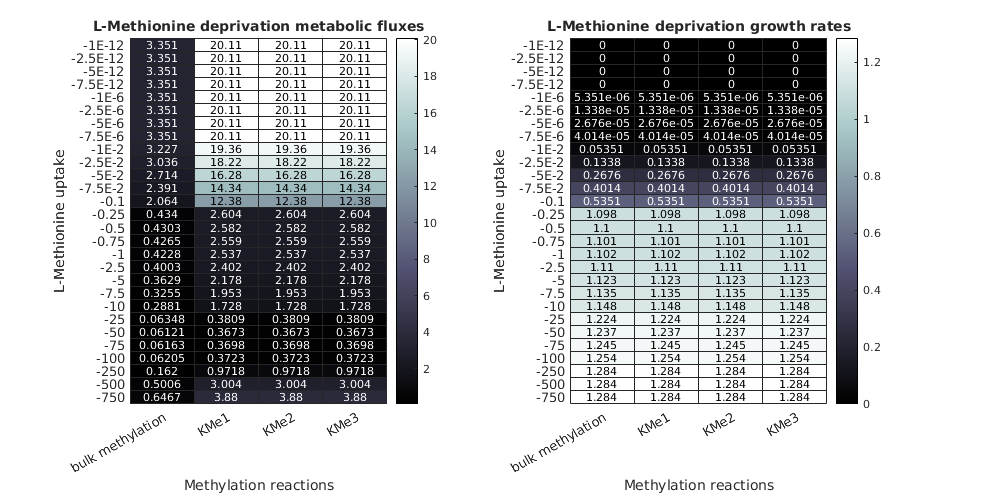

figure
subplot(1, 2, 1)
heatmap(deprivation_flux, ...
    'XData', dm_labels, ...
    'YData', met_uptake', ...
    'Colormap', bone);
xlabel("Methylation reactions"); ylabel("L-Methionine uptake");
title("L-Methionine deprivation metabolic fluxes");

subplot(1, 2, 2)
heatmap(deprivation_grate, ...
    'XData', dm_labels, ...
    'YData', met_uptake', ...
    'Colormap', bone);
xlabel("Methylation reactions"); ylabel("L-Methionine uptake");
title("L-Methionine deprivation growth rates");
set(gcf,'position',[0, 0, 1000, 500]);

### Scatter plots of the growth rate and methylation fluxes across different uptake rates

Next, I plotted the methylation flux and growth rates as a function of the methionine substrate uptake rates.

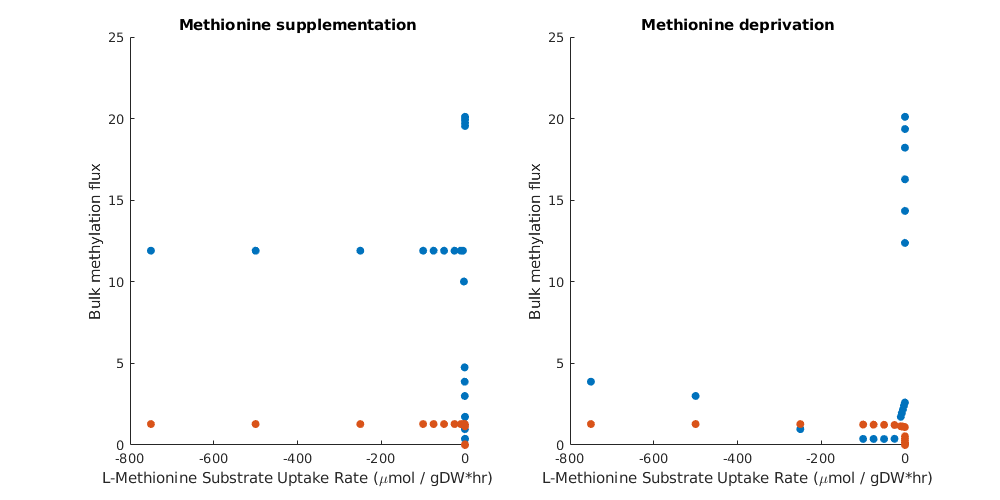

figure;

% Nutrient supplementation
subplot(1, 2, 1)
hold on;
met_uptake = [-1E-12, -2.5E-12, -5E-12, -7.5E-12, ...
              -1E-6, -2.5E-6, -5E-6, -7.5E-6, ...
              -1E-2, -2.5E-2, -5E-2, -7.5E-2, ...
              -0.1 , -0.25,   -0.5,  -0.75, ...
              -1,    -2.5,    -5,    -7.5, ...
              -10,   -25,     -50,   -75, ...
              -100,  -250,    -500,  -750];
scatter(met_uptake, supplementation_flux(:, 2), 'filled')
scatter(met_uptake, supplementation_grate(:, 2), 'filled')

xlabel("L-Methionine Substrate Uptake Rate (\mumol / gDW*hr)");
ylabel("Bulk methylation flux")
title("Methionine supplementation")

% Nutrient deprivation
subplot(1, 2, 2)
hold on;

scatter(met_uptake, deprivation_flux(:, 2), 'filled')
scatter(met_uptake, deprivation_grate(:, 2), 'filled')
hold off;

xlabel("L-Methionine Substrate Uptake Rate (\mumol / gDW*hr)");
ylabel("Bulk methylation flux")
title("Methionine deprivation")
set(gcf,'position',[0, 0, 1000, 500]);


h = axes;
set(h,'xscale','log')

### Scatter plot of the product between metabolic fluxes and growth rate

Now I plotted the product between the metabolic fluxes and the growth rate, to see if this would be informative for determining the best substrate uptake rate to use.

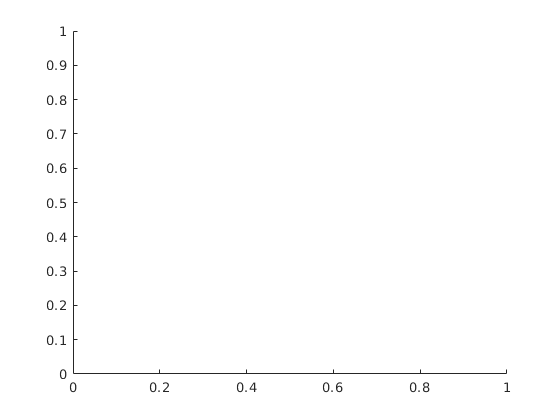

figure;

hold on;

scatter(met_uptake, supplementation_flux(:, 2) .* supplementation_grate(:, 2), ...
    'green', 'filled')

Error using scatter (line 78)
X and Y must be vectors of the same length.

scatter(met_uptake, deprivation_flux(:, 2) .* deprivation_grate(:, 2), ...
    'red', 'filled')
legend("Supplementation", "Deprivation", ...
    "Location", "bestoutside")

xlabel("L-Methionine Substrate Uptake Rate ( \mumol / gDW * hr )");
ylabel("Bulk methylation flux")
title("Methionine supplementation")
set(gcf, ...
    'position',[0, 0, 1000, 750]);
set(gca, 'FontSize', 20);
h = axes;
set(h,'xscale','log')

Looking at the growth rates, the substrate uptake rate that maximized the growth rate while showing metabolic fluxes that we expect is -100. Thus, I re-computed the metabolic fluxes for methylation under various medium conditions.

Set the lower bound for methionine uptake

% Set methionine lower bound to a really small number
[~, pos] = ismember({'EX_met_L_e'}, eGEM.rxns);
eGEM.lb(pos) = -1;

% Activity coefficient for demand reactions
epsilon_methylation = 0.069;
epsilon_acetylation = 1E-3;
for i = 1:length(dm_reactions)
    if contains(lower(dm_reactions(i)), "ac")
        epsilon(i, 1) = epsilon_acetylation;
    else
        epsilon(i, 1) = epsilon_methylation;
    end
end

## Nutrient perturbation using the best substrate uptake rate

tmp = eGEM;

% Demand reaction layer
for r = 1:length(dm_reactions)
    [~, rxnPos] = ismember(dm_reactions(r), tmp.rxns);
    
    % Supplementation / deprivation layer
    for kappatype = 1:2
        if kappatype == 1 % 1 = supplementation
            kappa  = 10; 
        else              % 2 = deprivation
            kappa = 0.01;
        end 
        
        % Nutrient perturbation layer
        for i = 1:50
            mod_kap = kappa;
            if (kappatype == 2) & (ismember(i,[2, 3, 5:19])) % Trace elements
                mod_kap = kappa / 100;
            elseif (kappatype == 1) & (ismember(i, [1;4]))   % Glucose / Glutamine
                mod_kap = 3;
            end
            
            % Add activity to demand reactions
            tmp2 = tmp;
            tmp2.c(rxnPos) = epsilon(r);
            
            % Modify uptake rate based on supplementation or deprivation
            [~, pos]  = ismember(mediareactions1(i), tmp2.rxns);
            tmp2.lb(pos) = -media_exchange1(i) * mod_kap;
    
            [~, solution] = CFR(tmp2, hyperparams, onreactions, offreactions);
            
            tmp3 = tmp2;
            tmp3.lb(3743) = solution.x(3743) * 0.99;
            tmp3.c(3743)  = 0;                                                
            [~, solution] = CFR(tmp3, hyperparams, onreactions, offreactions);
            
            % Save flux and growth rate based on supplementation / deprivation
            if kappatype == 1
                supplementation_flux(i, r)  = solution.x(rxnPos);
                supplementation_grate(i, r) = solution.x(3743);
            else
                deprivation_flux(i, r)  = solution.x(rxnPos);
                deprivation_grate(i, r) = solution.x(3743);
            end
        end
    end
end

## Evaluate growth rate constraints

First set the RdBu colormap to be continuous.

%load ~/Data/CBM/eGEM/NutrientPerturbation/08052020_grate_lb.mat
% Colormap
redbluecmap = imresize(redbluecmap, [1000, 3]); 
redbluecmap = min(max(redbluecmap, 0), 1);

Next, we'll set up the labels for the axes.

% Set labels
dm_labels = strrep(dm_reactions, '_', ' ');
dm_labels = strrep(dm_labels, 'DM', '');

load ~/Data/Mappings/MediumComponentMaps/unique_nutrients.mat
medium = labels;

We'll set fluxes that are equal to 0 to be NaN for visualization purposes.

% Make some reactions black for none
supplementation_flux(supplementation_flux == 0)             = NaN; 
supplementation_grate(supplementation_grate == 0)           = NaN;
deprivation_flux(deprivation_flux == 0)                     = NaN;         
deprivation_grate(deprivation_grate == 0)                   = NaN;

### Metabolic flux heatmap

Finally, we can construct the two heatmaps side-by-side, where the left one is nutrient supplementation and the right one is nutrient deprivation.

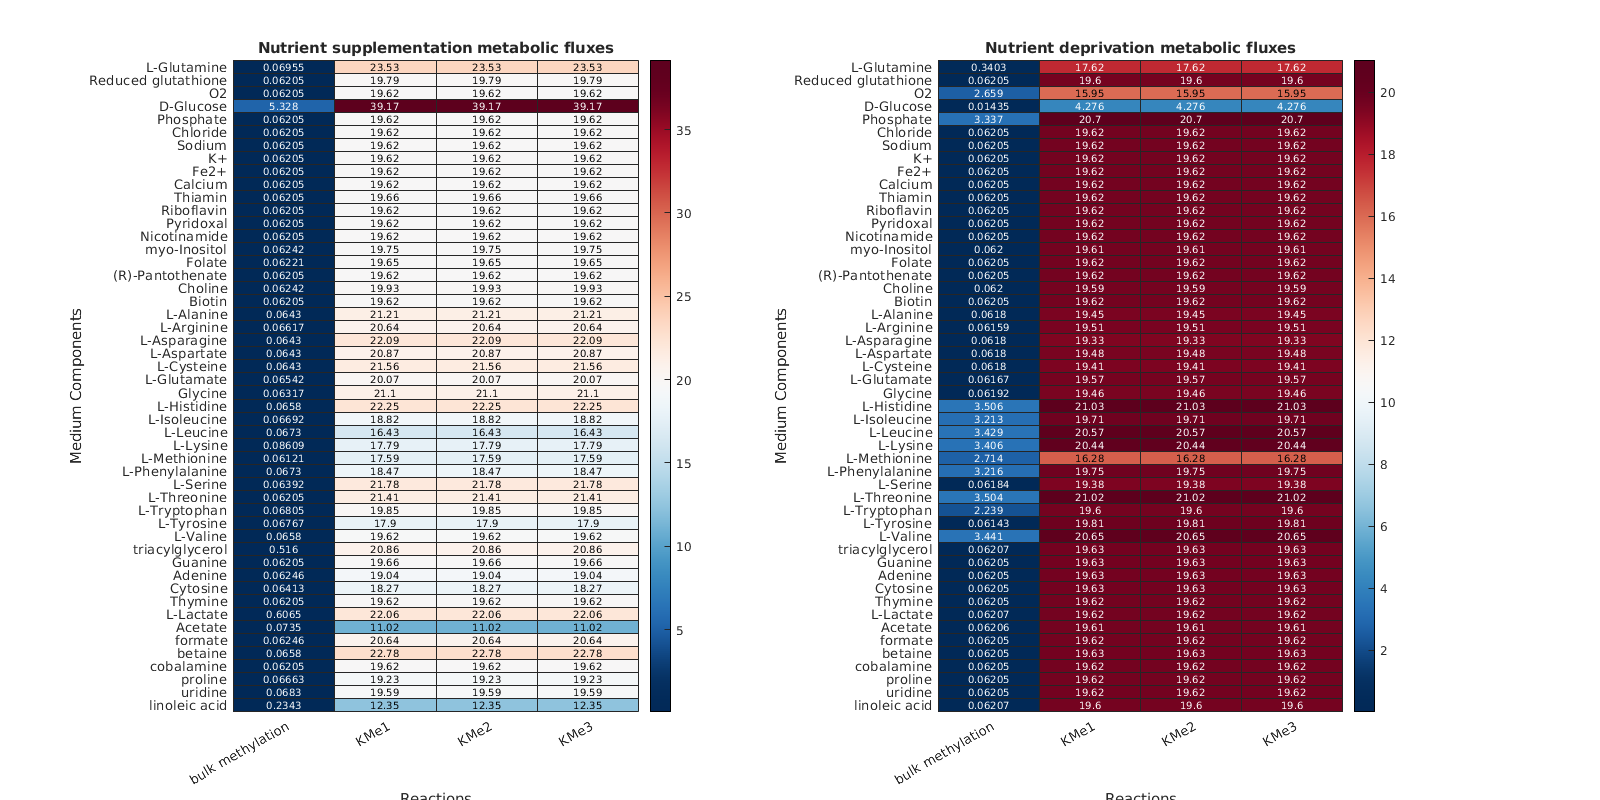

figure;
% Nutrient supplementation heatmap
subplot(1, 2, 1);
heatmap(supplementation_flux, ...
        'YData', medium, ...
        'XData', dm_labels', ...
        'Colormap', redbluecmap, ...
        'ylabel', 'Medium Components', ...
        'xlabel', 'Reactions', ...
        'title', 'Nutrient supplementation metabolic fluxes', ...
        'FontSize', 10, ...
        'FontName', 'Helvetica');

% Nutrient deprivation heatmap 
subplot(1, 2, 2);
heatmap(deprivation_flux, ...
        'YData', medium, ...
        'XData', dm_labels', ...
        'Colormap', redbluecmap, ...
        'ylabel', 'Medium Components', ...
        'xlabel', 'Reactions', ...
        'title', 'Nutrient deprivation metabolic fluxes', ...
        'FontSize', 10, ...
        'FontName', 'Helvetica');
set(gcf,'position',[0, 0, 1600, 800]);

## Conclusions

In the plot, the methionine supplementation results in higher methylation fluxes than methionine deprivation. However, other nutrients don't have much of an impact.